# Praktikum 2: Aufgabe 2

load('Prak2_A2Daten.mat');


figD = figure('Name', 'Daten', 'WindowStyle', 'docked');
scatter(tr, gr, 'DisplayName','Messdaten');
xlabel('Zeit t'), ylabel('Sprungantwort g(t)');
title('Sprungantwort eines PT1-Glieds');
legend('Location','nw');
N = length(tr);

## Energielandschaft

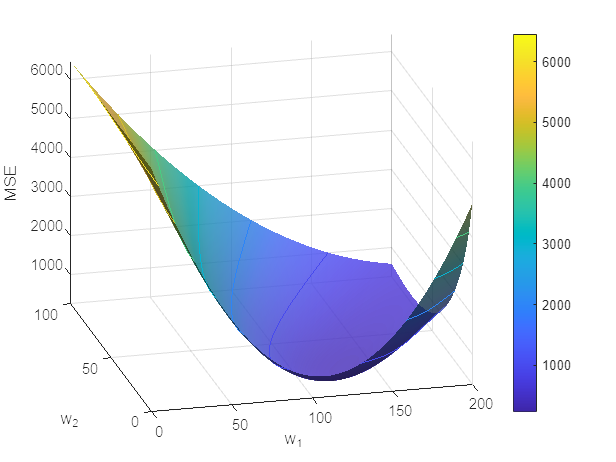

[W1, W2] = meshgrid(linspace(0,200, 200), linspace(0,100, 200));
MSE = zeros(size(W1));
for r=1:size(W1,1)
    for c=1:size(W1,2)
        yfit = W1(r,c).*(1-exp(-tr/W2(r,c)));
        MSE(r,c) = 1/(2*N)* sum( (gr-yfit).^2);
    end
end

% Darstellung in 3D und in 2D als Contour-Plot
f3D = figure('Name', 'MSE-3D', 'WindowStyle', 'docked');
MSEcut = MSE;
   % Abschneiden zur besseren Darstellung der Farben
surf(W1, W2, MSEcut);
hold on;
contour3(W1, W2, MSEcut);

hold off;
xlabel('w_1'), ylabel('w_2'), zlabel('MSE');
shading interp;  light, lighting gouraud, material dull
alpha(0.8)
colorbar;

[func, gradFunc] = createTask2Funcs(tr, gr);
w0t = [10;10];
[wopt, wtrack] = gaEinfach(gradFunc, eta, w0t, nIts);

wopt =   130.9384
   23.1383


% Auswerten der Kostenfunktion auf der Abstiegsspur
MSEtrack = zeros(nIts, 1);
for it=1:nIts
    MSEtrack(it) = func(wtrack(:,it));
end

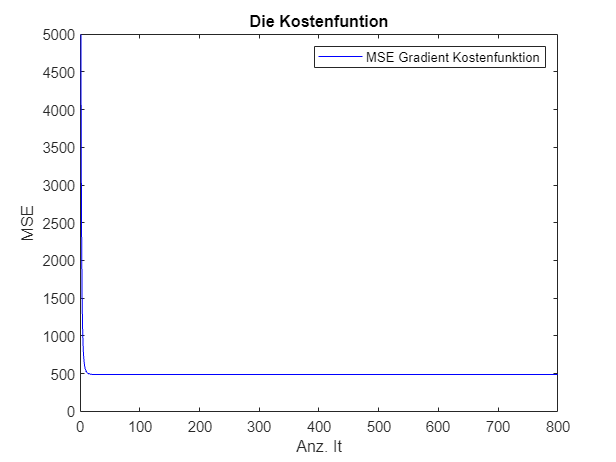

figK = figure('Name', 'MSE', 'WindowStyle', 'docked');
plot(1:nIts, MSEtrack, 'b', 'DisplayName', 'MSE Gradient Kostenfunktion')
legend;
xlabel('Anz. It'); ylabel('MSE');
title('Die Kostenfuntion');

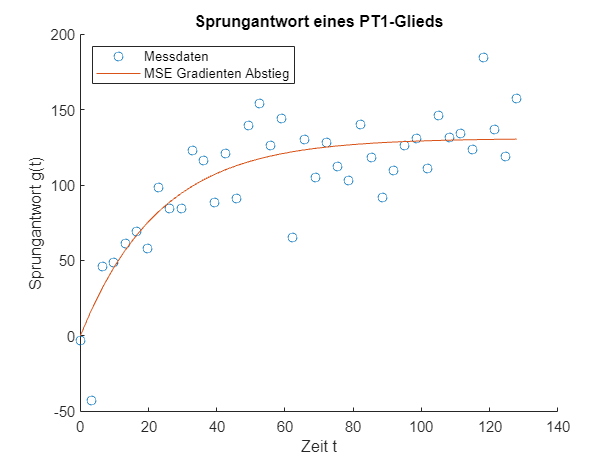

figure(figD);
trt = wopt(1) .* (1-exp(-tr/wopt(2)));
hold on;
plot(tr, trt, 'DisplayName', 'MSE Gradienten Abstieg')
hold off;